**AVD Group 01**

Hanchen Li

Please see **report** for theory and explaination, be aware of the **units** in angle

% House Keeping
clear
clc
close all

g = 9.80665;                          % Standard acceleration of gravity (m/s^2)

## **1. Neutral Point**

**Find fuselage coefficient of pitching moment**

x_c_4 = 32 + 3.5206; % Wing-root 1/4 chord position (m) % Undefined

L_f = 75.5;          % Total fuselage length (m)

% Find K_f via NACA TR 177

x_c_4 / L_f

ans = 0.4705


K_f = 1.44;          % Undefined

w_f = 6.88;          % Fuselage maximum width (m)

c = 9.84;            % Mean chord length (m) % Undefined

S_w = 639.23;        % Reference wing area (m^2)

d_CM_f = K_f * (L_f * (w_f ^ 2)) / (c * S_w) % (1/rad)

d_CM_f = 0.8182

**Find wing's zero lift pitching moment**

AR = 6.61;              % Aspect Ratio

Sweep = 26.75;          % Wing quarter chord sweep (degree)
Sweep = deg2rad(Sweep); % Wing quarter chord sweep (rad)

twist = 3.9;            % Wing twist (degree)

i_w = -0.1849;          % Wing setting angle (degree)
i_w = deg2rad(i_w);     % Wing setting angle (rad)

C_m_airf_0 = -0.13;     % Incompressible airfoil zero lift pitching moment

d_CL_w_0 = 3.228;       % Incompressible wing lift curve slope (1/rad) % Undefined

% Wing's zero lift pitching moment 'coefficient'
k_C_m0_w = (C_m_airf_0 * (AR * (cos(Sweep) ^ 2)) / (AR + 2 * cos(Sweep)) - 0.01 * twist) / d_CL_w_0

k_C_m0_w = -0.0374

**Other input parameters**

n_h = 0.9;             % Tail efficiency factor

B_w = 65;              % Wing span (m)

Taper = 3.5796 / 17;   % Wing taper ratio

x_ac_w_0 = 32 + 11.34; % Wing aerodynamic center at M=0 (m)

x_ac_h_0 = 72.2;       % Wing aerodynamic center at M=0 (m)

h_h = 5.3;             % Vertical distance between wing and horizontal tailplane chord (m)

l_h = x_ac_h_0 - x_ac_w_0; % (m)

S_h = 87.20;           % Horizontal tailplane area (m^2)

Z_t = -0.05;           % Thrustline

**Find compressible effect on aerodynamic center**

x_ac_M

% x_ac = x_ac_M(x_ac_0, M, S_wing)

**Find downwash derivative**

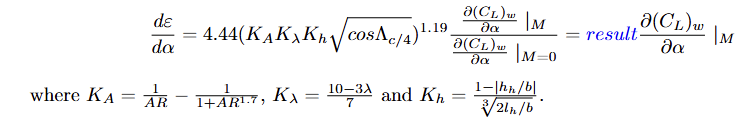

K_A = 1 / AR - 1 / (1 + AR ^ 1.7);

K_Taper = (10 - 3 * Taper) / 7;

K_h = (1 - abs(h_h / B_w)) / ((2 * l_h / B_w) ^ (1 / 3));

% Downwash derivative 'coefficient'
k_d_downwash = (4.44 * (K_A * K_Taper * K_h * (cos(Sweep)) ^ 0.5) ^ 1.19) / d_CL_w_0

k_d_downwash = 0.1280

results


$$x_{\mathrm{np}} =\frac{\frac{{d\left(C_L \right)}_W }{d\alpha }{\left(x_{\mathrm{ac}} \right)}_w -\frac{{\delta \left(C_M \right)}_f }{\delta \alpha }\bar{c} +\eta_h \frac{{d\left(C_L \right)}_h }{d\alpha }\left(1-\frac{d\varepsilon }{d\alpha }\right)\frac{S_h }{S_w }{\left(x_{\mathrm{ac}} \right)}_h }{\frac{{d\left(C_L \right)}_W }{d\alpha }+\eta_h \frac{{d\left(C_L \right)}_h }{d\alpha }\left(1-\frac{d\varepsilon }{d\alpha }\right)\frac{S_h }{S_w }}$$


**0-1** Takeoff **&** **4-5** Missed approach

a_0_w_TO = -0.8848;  % Wing takeoff zero lift angle of attack (rad)
d_CL_w_TO = 3.4049;  % Wing takeoff lift curve slope (1/rad)

a_0_h_TO = -0.8848;  % Horizontal tailplane takeoff zero lift angle of attack (rad)
d_CL_h_TO = 3.4049;  % Horizontal tailplane takeoff lift curve slope (1/rad)

CD_TO = 0;           % Takeoff drag coefficient

% No compressibility effect 
x_ac_w_TO = x_ac_w_0

x_ac_w_TO = 43.3400

x_ac_h_TO = x_ac_h_0

x_ac_h_TO = 72.2000


d_downwash_TO = k_d_downwash * d_CL_w_0

d_downwash_TO = 0.4132


C_m0_w_TO = k_C_m0_w * d_CL_w_0

C_m0_w_TO = -0.1206


% Find neutral point
x_np_TO = (d_CL_w_TO * x_ac_w_TO - d_CM_f * c + n_h * d_CL_h_TO * (1 - d_downwash_TO) * (S_h / S_w) * x_ac_h_TO) / ...
    ((d_CL_w_TO + n_h * d_CL_h_TO * (1 - d_downwash_TO) * (S_h / S_w)))

x_np_TO = 43.0738

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

a_0_w_c1 = -0.113;  % Wing 1st cruise zero lift angle of attack (rad)
d_CL_w_c1 = 3.9523;  % Wing 1st cruise lift curve slope (1/rad)

a_0_h_c1 = -0.113;  % Horizontal tailplane 1st cruise zero lift angle of attack (rad)
d_CL_h_c1 = 3.9523;  % Horizontal tailplane 1st cruise lift curve slope (1/rad)

CD_c1 = 0;           % 1st cruise drag coefficient

% Compressibility effect 
M_c1 = 0.83;

x_ac_w_c1 = x_ac_M(x_ac_w_0, M_c1, S_w)

x_ac_w_c1 = 44.1370

x_ac_h_c1 = x_ac_M(x_ac_h_0, M_c1, S_h)

x_ac_h_c1 = 72.4944


d_downwash_cmax = k_d_downwash * d_CL_w_c1

d_downwash_cmax = 0.5060


C_m0_w_c1 = k_C_m0_w * d_CL_w_c1

C_m0_w_c1 = -0.1477


% Find neutral point
x_np_c1 = (d_CL_w_c1 * x_ac_w_c1 - d_CM_f * c + n_h * d_CL_h_c1 * (1 - d_downwash_cmax) * (S_h / S_w) * x_ac_h_c1) / ...
    ((d_CL_w_c1 + n_h * d_CL_h_c1 * (1 - d_downwash_cmax) * (S_h / S_w)))

x_np_c1 = 43.8382

**3-4** Descent to land **&** **7-8** Descent to land

a_0_w_L = -0.8051;  % Wing landing zero lift angle of attack (rad)
d_CL_w_L = 3.8117;  % Wing landing lift curve slope (1/rad)

a_0_h_L = -0.8051;  % Horizontal tailplane landing zero lift angle of attack (rad)
d_CL_h_L = 3.8117;  % Horizontal tailplane landing lift curve slope (1/rad)

CD_L = 0;           % landing drag coefficient

% No compressibility effect 
x_ac_w_L = x_ac_w_0

x_ac_w_L = 43.3400

x_ac_h_L = x_ac_h_0

x_ac_h_L = 72.2000


d_downwash_L = k_d_downwash * d_CL_w_0

d_downwash_L = 0.4132


C_m0_w_L = k_C_m0_w * d_CL_w_0

C_m0_w_L = -0.1206


% Find neutral point
x_np_L = (d_CL_w_L * x_ac_w_L - d_CM_f * c + n_h * d_CL_h_L * (1 - d_downwash_L) * (S_h / S_w) * x_ac_h_L) / ...
    ((d_CL_w_L + n_h * d_CL_h_L * (1 - d_downwash_L) * (S_h / S_w)))

x_np_L = 43.3092

**5-6** Cruise to alternate destination 370 km away

a_0_w_c2 = -0.126;  % Wing 2nd cruise zero lift angle of attack (rad)
d_CL_w_c2 = 3.5742;  % Wing 2nd cruise lift curve slope (1/rad)

a_0_h_c2 = -0.126;  % Horizontal tailplane 2nd cruise zero lift angle of attack (rad)
d_CL_h_c2 = 3.5742;  % Horizontal tailplane 2nd cruise lift curve slope (1/rad)

CD_c2 = 0;           % 2nd cruise drag coefficient

% Compressibility effect 
M_c2 = 0.6460;

x_ac_w_c2 = x_ac_M(x_ac_w_0, M_c2, S_w)

x_ac_w_c2 = 43.5373

x_ac_h_c2 = x_ac_M(x_ac_h_0, M_c2, S_h)

x_ac_h_c2 = 72.2729


d_downwash_c2 = k_d_downwash * d_CL_w_c2

d_downwash_c2 = 0.4576


C_m0_w_c2 = k_C_m0_w * d_CL_w_c2

C_m0_w_c2 = -0.1335


% Find neutral point
x_np_c2 = (d_CL_w_c2 * x_ac_w_c2 - d_CM_f * c + n_h * d_CL_h_c2 * (1 - d_downwash_c2) * (S_h / S_w) * x_ac_h_c2) / ...
    ((d_CL_w_c2 + n_h * d_CL_h_c2 * (1 - d_downwash_c2) * (S_h / S_w)))

x_np_c2 = 43.2197

**6-7** Loiter at 5000 ft for 45 minutes

a_0_w_loi = -0.1369;  % Wing 2nd cruise zero lift angle of attack (rad)
d_CL_w_loi = 3.311;  % Wing 2nd cruise lift curve slope (1/rad)

a_0_h_loi = -0.1369;  % Horizontal tailplane 2nd cruise zero lift angle of attack (rad)
d_CL_h_loi = 3.311;  % Horizontal tailplane 2nd cruise lift curve slope (1/rad)

% Compressibility effect 
M_loi = 0.3942;

x_ac_w_loi = x_ac_M(x_ac_w_0, M_loi, S_w)

x_ac_w_loi = 43.3400

x_ac_h_loi = x_ac_M(x_ac_h_0, M_loi, S_h)

x_ac_h_loi = 72.2000


d_downwash_loi = k_d_downwash * d_CL_w_loi

d_downwash_loi = 0.4239


C_m0_w_loi = k_C_m0_w * d_CL_w_loi

C_m0_w_loi = -0.1237


% Find neutral point
x_np_loi = (d_CL_w_loi * x_ac_w_loi - d_CM_f * c + n_h * d_CL_h_loi * (1 - d_downwash_loi) * (S_h / S_w) * x_ac_h_loi) / ...
    ((d_CL_w_loi + n_h * d_CL_h_loi * (1 - d_downwash_loi) * (S_h / S_w)))

x_np_loi = 42.9757

***** Cruise at M = 0.85

a_0_w_cmax = -0.113;  % Wing 1st cruise zero lift angle of attack (rad)
d_CL_w_cmax = 3.9523;  % Wing 1st cruise lift curve slope (1/rad)

a_0_h_cmax = -0.113;  % Horizontal tailplane 1st cruise zero lift angle of attack (rad)
d_CL_h_cmax = 3.9523;  % Horizontal tailplane 1st cruise lift curve slope (1/rad)

% Compressibility effect 
M_cmax = 0.85;

x_ac_w_cmax = x_ac_M(x_ac_w_0, M_cmax, S_w)

x_ac_w_cmax = 44.2330

x_ac_h_cmax = x_ac_M(x_ac_h_0, M_cmax, S_h)

x_ac_h_cmax = 72.5298


d_downwash_cmax = k_d_downwash * d_CL_w_cmax

d_downwash_cmax = 0.5060


C_m0_w_cmax = k_C_m0_w * d_CL_w_cmax

C_m0_w_cmax = -0.1477


% Find neutral point
x_np_cmax = (d_CL_w_cmax * x_ac_w_cmax - d_CM_f * c + n_h * d_CL_h_cmax * (1 - d_downwash_cmax) * (S_h / S_w) * x_ac_h_cmax) / ...
    ((d_CL_w_cmax + n_h * d_CL_h_cmax * (1 - d_downwash_cmax) * (S_h / S_w)))

x_np_cmax = 43.9307

***** Absolute ceiling

## **2. Static Margin**

**Read the CG value**

% This need to be refresh to the latest version of weight and CG

Fuel useage in mission profile

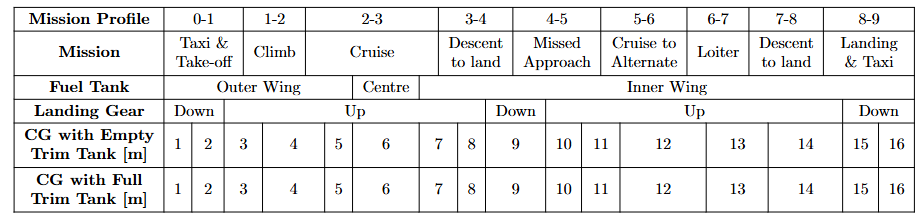

x_f_empty = load('x_f_empty.mat');
x_f_empty = x_f_empty.x_f_empty

x_f_empty =    36.7047   36.6028   36.5925   36.5406   36.4123   36.4967   36.0586   36.0390   36.0559   36.0390   36.0199   35.9633   35.9297   35.9163   35.9343   35.9176


x_f_full = load('x_f_full.mat');
x_f_full = x_f_full.x_f_full

x_f_full =    36.7977   36.6987   36.6885   36.6380   36.5481   36.6591   36.2472   36.2295   36.2464   36.2295   36.2122   36.1611   36.1308   36.1187   36.1367   36.1216



W_mission = load('W_mission.mat');
W_mission = W_mission.W_mission

W_mission = 1.0e+05 *

    4.2990    4.1700    4.1700    4.1075    3.9605    3.2871    2.5452    2.5198    2.5198    2.5198    2.4955    2.4261    2.3868    2.3714    2.3714    2.3525


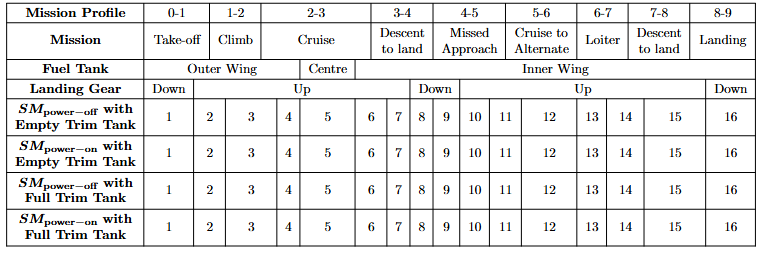

**0-1** Takeoff

% Takeoff Gear down
SM_off_empty (1, 1) = (x_np_TO - x_f_empty(1, 2)) / c;
SM_off_full (1, 1) = (x_np_TO - x_f_full(1, 2)) / c;

W_SM (1, 1) = W_mission (1, 2);

% Takeoff Gear up
SM_off_empty (1, 2) = (x_np_TO - x_f_empty(1, 3)) / c;
SM_off_full (1, 2) = (x_np_TO - x_f_full(1, 3)) / c;

W_SM (1, 2) = W_mission (1, 3);

**1-2** Climb and accelerate to cruise

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Cruise 1 start
SM_off_empty (1, 3) = (x_np_c1 - x_f_empty(1, 4)) / c;
SM_off_full (1, 3) = (x_np_c1 - x_f_full(1, 4)) / c;

W_SM (1, 3) = W_mission (1, 4);

% Outer wing tank end
SM_off_empty (1, 4) = (x_np_c1 - x_f_empty(1, 5)) / c;
SM_off_full (1, 4) = (x_np_c1 - x_f_full(1, 5)) / c;

W_SM (1, 4) = W_mission (1, 5);

% Centre wing tank end
SM_off_empty (1, 5) = (x_np_c1 - x_f_empty(1, 6)) / c;
SM_off_full (1, 5) = (x_np_c1 - x_f_full(1, 6)) / c;

W_SM (1, 5) = W_mission (1, 6);

**3-4** Descent to land

% Cruise 1 end
SM_off_empty (1, 6) = (x_np_c1 - x_f_empty(1, 7)) / c;
SM_off_full (1, 6) = (x_np_c1 - x_f_full(1, 7)) / c;

W_SM (1, 6) = W_mission (1, 7);

% Landing 1 Gear up
SM_off_empty (1, 7) = (x_np_L - x_f_empty(1, 8)) / c;
SM_off_full (1, 7) = (x_np_L - x_f_full(1, 8)) / c;

W_SM (1, 7) = W_mission (1, 8);

% Landing 1 Gear down
SM_off_empty (1, 8) = (x_np_L - x_f_empty(1, 9)) / c;
SM_off_full (1, 8) = (x_np_L - x_f_full(1, 9)) / c;

W_SM (1, 8) = W_mission (1, 9);

**4-5** Missed approach, followed by clmb and accelerate to alternate

% Takeoff 2 Gear down
SM_off_empty (1, 9) = (x_np_TO - x_f_empty(1, 10)) / c;
SM_off_full (1, 9) = (x_np_TO - x_f_full(1, 10)) / c;

W_SM (1, 9) = W_mission (1, 10);

% Takeoff 2 Gear up
SM_off_empty (1, 10) = (x_np_TO - x_f_empty(1, 10)) / c;
SM_off_full (1, 10) = (x_np_TO - x_f_full(1, 10)) / c;

W_SM (1, 10) = W_mission (1, 10);

**5-6** Cruise to alternate destination 370 km away

% Cruise 2 Start
SM_off_empty (1, 11) = (x_np_c2 - x_f_empty(1, 11)) / c;
SM_off_full (1, 11) = (x_np_c2 - x_f_full(1, 11)) / c;

W_SM (1, 11) = W_mission (1, 11);

% Cruise 2 end
SM_off_empty (1, 12) = (x_np_c2 - x_f_empty(1, 12)) / c;
SM_off_full (1, 12) = (x_np_c2 - x_f_full(1, 12)) / c;

W_SM (1, 12) = W_mission (1, 12);

**6-7** Loiter at 5000 ft for 45 minutes

% Loiter start
SM_off_empty (1, 13) = (x_np_loi - x_f_empty(1, 12)) / c;
SM_off_full (1, 13) = (x_np_loi - x_f_full(1, 12)) / c;

W_SM (1, 13) = W_mission (1, 12);

**7-8** Descent to land

% Loiter end
SM_off_empty (1, 14) = (x_np_loi - x_f_empty(1, 13)) / c;
SM_off_full (1, 14) = (x_np_loi - x_f_full(1, 13)) / c;

W_SM (1, 14) = W_mission (1, 13);

**8-9** Landing

% Landing 2 Gear up
SM_off_empty (1, 15) = (x_np_L - x_f_empty(1, 14)) / c;
SM_off_full (1, 15) = (x_np_L - x_f_full(1, 14)) / c;

W_SM (1, 15) = W_mission (1, 14);

% Landing 2 Gear down
SM_off_empty (1, 16) = (x_np_L - x_f_empty(1, 15)) / c;
SM_off_full (1, 16) = (x_np_L - x_f_full(1, 15)) / c;

W_SM (1, 16) = W_mission (1, 15);

***** Cruise at M = 0.86

***** Absolute ceiling

**Overall**

SM_off_empty * 100

ans =    65.7626   65.8664   74.1623   75.4669   74.6085   79.0614   73.8842   73.7123   71.4921   71.4921   73.1694   73.7447   71.2644   71.6057   75.1310   74.9484


SM_on_empty = SM_off_empty - 0.02;
SM_on_empty * 100

ans =    63.7626   63.8664   72.1623   73.4669   72.6085   77.0614   71.8842   71.7123   69.4921   69.4921   71.1694   71.7447   69.2644   69.6057   73.1310   72.9484


SM_off_full * 100

ans =    64.7877   64.8916   73.1727   74.0862   72.9587   77.1448   71.9483   71.7764   69.5562   69.5562   71.2147   71.7341   69.2537   69.5619   73.0740   72.8914


SM_on_full = SM_off_full - 0.02;

SM_on_full * 100

ans =    62.7877   62.8916   71.1727   72.0862   70.9587   75.1448   69.9483   69.7764   67.5562   67.5562   69.2147   69.7341   67.2537   67.5619   71.0740   70.8914


**Plot the SM - mission profile**

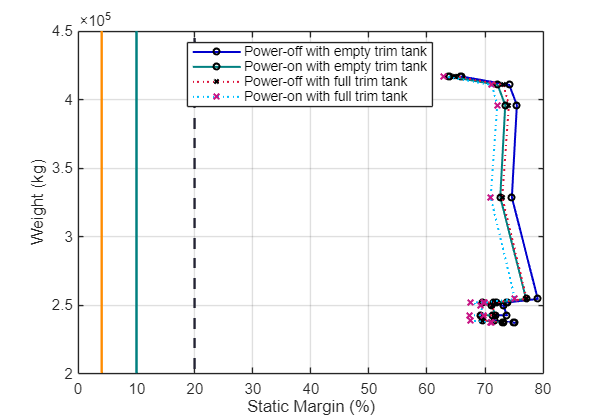

figure(1)

clf;

plot(SM_off_empty * 100, W_SM, 'o-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25, 'Markersize', 3.75 , 'MarkerEdgeColor', [0/255 0/255 0/255])
hold on % Engine off SM without trim tank
plot(SM_on_empty * 100, W_SM, 'o-', 'Color',  [0/255 128/255 128/255], 'LineWidth', 1.25, 'Markersize', 3.75 , 'MarkerEdgeColor', [0/255 0/255 0/255])
hold on % Engine on SM without trim tank
plot(SM_off_full * 100, W_SM, 'x:', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25, 'Markersize', 3.75 , 'MarkerEdgeColor', [0/255 0/255 0/255]);
hold on % Engine off SM with trim tank
plot(SM_on_full * 100, W_SM, 'x:', 'Color',  [0/255 191/255 255/255], 'LineWidth', 1.25, 'Markersize', 5 , 'MarkerEdgeColor', [199/255 21/255 133/255])
hold on % Engine on SM with trim tank
plot([4 4], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward good range
plot([10 10], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold on % Aft good range
plot([20 20], [0 5e5], '--', 'Color', [35/255 35/255 51/255], 'LineWidth', 1.5);
hold off % Aft limit

% Hide legend for final version
legend('Power-off with empty trim tank', 'Power-on with empty trim tank', 'Power-off with full trim tank', ...
    'Power-on with full trim tank',...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)

xlabel('Static Margin (%)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

%xlim([35 37.5]);
ylim([2e5 4.5e5]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 500 350]); % show plot with larger size

## 3. Trim Analysis